## Code for training EEG and EMG classifiers

#### Load data

raw_eeg_data = load("data_sets\eeg_with_electrodes.txt");
eeg_fs=200; % EEG sample rate
raw_emg_data = load("data_sets\emg_1_channel.txt");
emg_fs=1000; % EMG sample rate

#### Display data lost

EEG

fprintf("=======================================================================================")

data_lost = 0;
expected_data = length(raw_eeg_data);
for i = 2:length(raw_eeg_data)
    if raw_eeg_data(i,1) ~= mod(raw_eeg_data(i-1,1) + 1, 200)
        data_lost = data_lost + 1;
    end
end
disp(['EEG Data lost: ', num2str((data_lost/expected_data)*100,'%.2f'),'%']);

EEG Data lost: 100.00%


EMG

data_lost = 0;
[expected_data, ~] = size(raw_emg_data);
for i = 2:expected_data
    % If next package doesn't have last package ID + 1, then a package has been lost
    % EMG package ID is mod 1000
    if raw_emg_data(i,3) ~= mod(raw_emg_data(i-1,3) + 1, 1000)
        data_lost = data_lost + 1;
    end
end
disp(['EMG Data lost: ', num2str((data_lost/expected_data)*100,'%.2f'),'%']);

EMG Data lost: 0.00%


fprintf("=======================================================================================")

#### Display data quality

EEG

fprintf("=======================================================================================")

% Extract signal-to-noise (SNR), signal to noise and distortion ratio (SINAD), total harmonic distortion (THD).
sFE = signalTimeFeatureExtractor(SampleRate=eeg_fs, SNR = true, SINAD = true, THD = true);
fprintf("EEG data quality")

EEG data quality

eeg_quality = extract(sFE,raw_eeg_data(:, 1:4));
fprintf('\nChannel 1:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',eeg_quality(:,1,1),eeg_quality(:,2,1), eeg_quality(:,3,1));


Channel 1:
SNR:	 -6.583505
SINAD:	 -5.364685
THD:	 -6.791417


fprintf('\nChannel 2:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',eeg_quality(:,1,2),eeg_quality(:,2,2), eeg_quality(:,3,2));


Channel 2:
SNR:	 -2.834357
SINAD:	 -Inf
THD:	 -2.834357


fprintf('\nChannel 3:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',eeg_quality(:,1,3),eeg_quality(:,2,3), eeg_quality(:,3,3));


Channel 3:
SNR:	 -4.472005
SINAD:	 -8.405563
THD:	 -4.603790


fprintf('\nChannel 4:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',eeg_quality(:,1,4),eeg_quality(:,2,4), eeg_quality(:,3,4));


Channel 4:
SNR:	 -2.580827
SINAD:	 -9.199911
THD:	 -2.702957


EMG

fprintf("EMG data quality")

EMG data quality

emg_quality = extract(sFE,raw_emg_data(:, 1));
fprintf('\nChannel 1:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',emg_quality(:,1,1),emg_quality(:,2,1), emg_quality(:,3,1));


Channel 1:
SNR:	 -14.090821
SINAD:	 -7.319155
THD:	 -14.106568


%fprintf('\nChannel 2:\nSNR:\t %f\nSINAD:\t %f\nTHD:\t %f\n',emg_quality(:,1,2),emg_quality(:,2,2), emg_quality(:,3,2));
fprintf("=======================================================================================")

#### Visualize signal

EEG

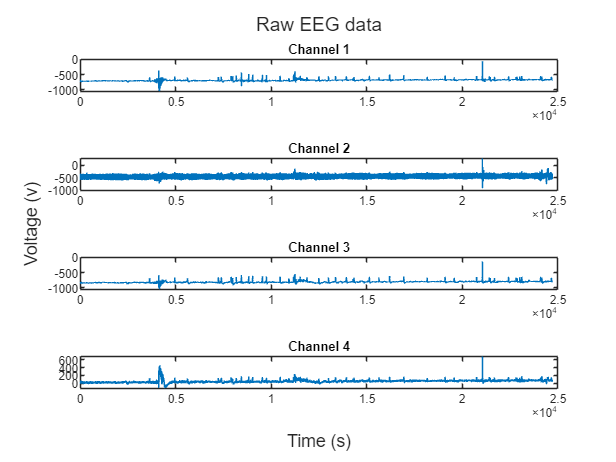

% Plot all EEG channels
figure
EEG_plot_handle = tiledlayout(4,1);
channel1_plot_handle = nexttile;
plot(raw_eeg_data(:,1))
title('Channel 1')
channel2_plot_handle = nexttile;
plot(raw_eeg_data(:,2))
title('Channel 2')
channel3_plot_handle = nexttile;
plot(raw_eeg_data(:,3))
title('Channel 3')
channel4_plot_handle = nexttile;
plot(raw_eeg_data(:,4))
title('Channel 4')

% Link x axis
linkaxes([channel1_plot_handle,channel2_plot_handle,channel3_plot_handle,channel4_plot_handle],'x');

% Add title etc
title(EEG_plot_handle,'Raw EEG data')
xlabel(EEG_plot_handle,'Time (s)')
ylabel(EEG_plot_handle,'Voltage (v)')

EMG

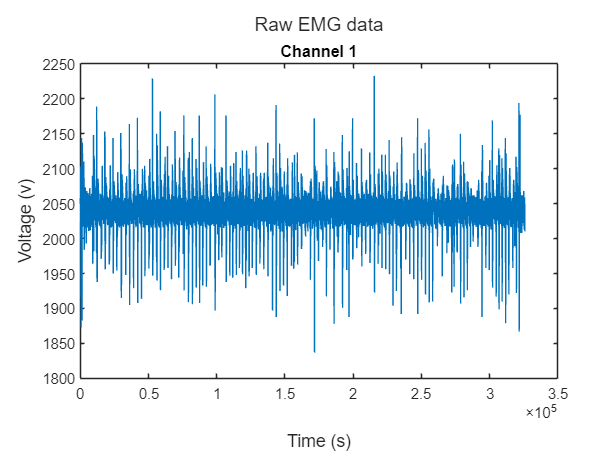

% Plot all EMG channels
figure
EMG_plot_handle = tiledlayout(1,1);
channel1_plot_handle = nexttile;
plot(raw_emg_data(:,1))
title('Channel 1')
%{
channel2_plot_handle = nexttile;
plot(raw_emg_data(:,2))
title('Channel 2')
%}

% Link x axis
%linkaxes([channel1_plot_handle,channel2_plot_handle],'x');

% Add title etc
title(EMG_plot_handle,'Raw EMG data')
xlabel(EMG_plot_handle,'Time (s)')
ylabel(EMG_plot_handle,'Voltage (v)')

fprintf("=======================================================================================")

#### Preprocessing

EEG

Artifact removal: [https://se.mathworks.com/matlabcentral/fileexchange/55413-wica-data-varargin](https://se.mathworks.com/matlabcentral/fileexchange/55413-wica-data-varargin) 

Dependency: [https://github.com/biotrump/RADICAL-matlab](https://github.com/biotrump/RADICAL-matlab) 

Dependency: [https://research.ics.aalto.fi/ica/fastica/](https://research.ics.aalto.fi/ica/fastica/) 

%--------------------------------------------------------------------------------------------------------

%{
% Median filtering of the baseline wandering which usually is of a frequency of about 0.5Hz, but can be higher with movement.
% Baseline wandering is usually caused by respiration, electrodes(like poor contact or internal changes) and motion.
% The values 24 and 80 is for a sampling frequency of 500Hz.
s_filt_1=medfilt1(raw_eeg_data(:,1:4),(eeg_fs/500)*24);
s_filt_2=medfilt1(s_filt_1,(eeg_fs/500)*80);
filtered_eeg_data = raw_eeg_data(:,1:4) - s_filt_2;
%}

% Remove baseline wandering and DC offset
% 4th order Butterworth highpass filter 0.1hz cut off frequency.
[n,d] = butter(4,(0.1)/(eeg_fs/2),"high");
filtered_eeg_data = filter(n,d,raw_eeg_data(:,1:4));

% Removal of 50Hz noise and all of it's harmonics up to 100Hz. 
% The noise is caused by magnetic fields generated by powerlines.
% Using a IIR notch filter of the fourth order as it's at that point the 50Hz noise peak on most signals practicaly becomes zero if a quality factor of about 25-35 is being used.
fo = 4;     % Filter order.
cf = 50/(eeg_fs/2); % Center frequency, value has to be between 0 and 1, where 1 is pi which is the Nyquist frequency which for our signal is Fs/2 = 500Hz.
qf = 30;   % Quality factor.
pbr = 1;   % Passband ripple, dB.
for k = 1:2
    notchSpecs  = fdesign.notch('N,F0,Q,Ap',fo,cf * k,qf,pbr);
    notchFilt = design(notchSpecs,'IIR','SystemObject',true);
    filtered_eeg_data = notchFilt(filtered_eeg_data); 
end


% Remove artifacts from EEG using wavelet enhanced ICA, W-ICA
[wIC,A,W,IC] = wICA(transpose(filtered_eeg_data));

Number of signals: 4
Number of samples: 24716
Calculating covariance...
Dimension not reduced.
Selected [ 4 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 39.4196 ]
Largest remaining (non-zero) eigenvalue [ 5186.2 ]
Sum of removed eigenvalues [ 0 ]
[ 100 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 6.43415e-15 ].
Used approach [ defl ].
Used nonlinearity [ pow3 ].
Starting ICA calculation...
IC 1 .............................................computed ( 45 steps ) 
IC 2 .............computed ( 13 steps ) 
IC 3 ......computed ( 6 steps ) 
IC 4 ..computed ( 2 steps ) 
Done.
Adding the mean back to the data.
Perforing wavelet thresholding


% Artifacts
artifacts = transpose(A*wIC);
% Subtract artifacts from original signal to get "artifact free" signal
filtered_eeg_data = filtered_eeg_data - artifacts;

% 1. 2. 3. 4. channel 1,2,3,4
% 5. labels
% 6. package ID
% 7. timestamp
filtered_eeg_data = [filtered_eeg_data raw_eeg_data(:,5:7)];

%--------------------------------------------------------------------------------------------------------

fprintf("=======================================================================================")

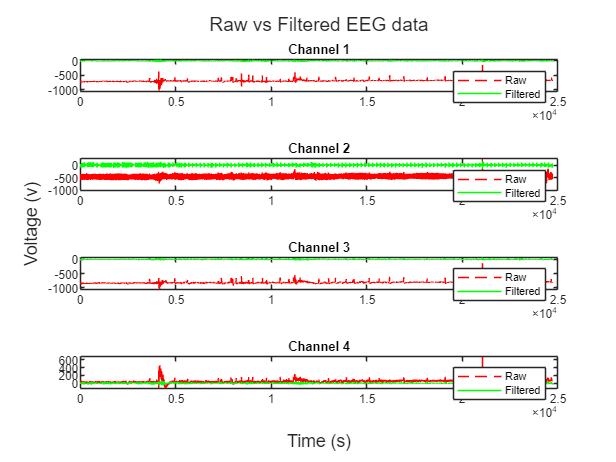

% Plot all EEG channels
figure
EEG_filtered_plot_handle = tiledlayout("vertical");
channel1_filtered_plot_handle = nexttile;
plot(raw_eeg_data(:,1), 'r--')
hold on
plot(filtered_eeg_data(:,1), 'g')
hold off
title('Channel 1')
legend('Raw','Filtered')
channel2_filtered_plot_handle = nexttile;
plot(raw_eeg_data(:,2), 'r--')
hold on
plot(filtered_eeg_data(:,2), 'g')
hold off
title('Channel 2')
legend('Raw','Filtered')
channel3_filtered_plot_handle = nexttile;
plot(raw_eeg_data(:,3), 'r--')
hold on
plot(filtered_eeg_data(:,3), 'g')
hold off
title('Channel 3')
legend('Raw','Filtered')
channel4_filtered_plot_handle = nexttile;
plot(raw_eeg_data(:,4), 'r--')
hold on
plot(filtered_eeg_data(:,4), 'g')
hold off
title('Channel 4')
legend('Raw','Filtered')

% Link x axis
linkaxes([channel1_filtered_plot_handle,channel2_filtered_plot_handle,channel3_filtered_plot_handle,channel4_filtered_plot_handle],'x');

% Add title etc
title(EEG_filtered_plot_handle,'Raw vs Filtered EEG data')
xlabel(EEG_filtered_plot_handle,'Time (s)')
ylabel(EEG_filtered_plot_handle,'Voltage (v)')

EMG

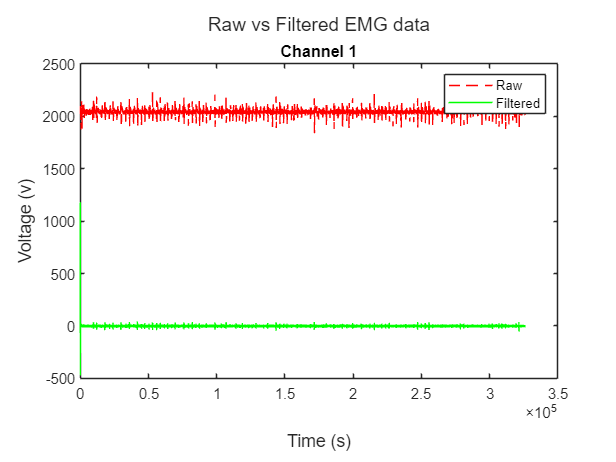

% Removal of the 0Hz(the DC offset) and high frequency noise.
% 20–500Hz fourth-order Butterworth bandpass filter.
[n,d] = butter(4,[20 499]/(emg_fs/2),"bandpass");
filtered_emg_data = filter(n,d,raw_emg_data(:,1));

% Removal of 50Hz noise and all of it's harmonics up to 150Hz. 
% The noise is caused by magnetic fields generated by powerlines.
% Using a IIR notch filter of the fourth order as it's at that point the 50Hz noise peak on most signals practicaly becomes zero if a quality factor of about 25-35 is being used.
fo = 4;     % Filter order.
cf = 50/(emg_fs/2); % Center frequency, value has to be between 0 and 1, where 1 is pi which is the Nyquist frequency which for our signal is Fs/2 = 500Hz.
qf = 30;   % Quality factor.
pbr = 1;   % Passband ripple, dB.
for k = 1:3
    notchSpecs  = fdesign.notch('N,F0,Q,Ap',fo,cf * k,qf,pbr);
    notchFilt = design(notchSpecs,'IIR','SystemObject',true);
    filtered_emg_data = notchFilt(filtered_emg_data); 
end

% 1. 2. channel 1,2
% 3. labels
% 4. package ID
% 5. time stamp
filtered_emg_data = [filtered_emg_data raw_emg_data(:,2:4)];

%--------------------------------------------------------------------------------------------------------

% Plot all EMG channels
figure
EMG_plot_handle = tiledlayout(1,1);
channel1_filtered_plot_handle = nexttile;
plot(raw_emg_data(:,1),'r--')
hold on
plot(filtered_emg_data(:,1),'g')
hold off
title('Channel 1')
legend('Raw','Filtered')
%{
channel2_filtered_plot_handle = nexttile;
plot(raw_emg_data(:,2),'r--')
hold on
plot(filtered_emg_data(:,2),'g')
hold off
title('Channel 2')
legend('Raw','Filtered')
%}

% Link x axis
%linkaxes([channel1_filtered_plot_handle,channel2_filtered_plot_handle],'x');

% Add title etc
title(EMG_plot_handle,'Raw vs Filtered EMG data')
xlabel(EMG_plot_handle,'Time (s)')
ylabel(EMG_plot_handle,'Voltage (v)')

fprintf("=======================================================================================")

#### Segmentation

EEG

% Window EEG signal into 500ms windows with 100ms overlap
window_size = 0.250;                        % window size s
overlap = 0.050;                            % window overlap s
[eeg_1, egg_remaining_samples] = buffer(filtered_eeg_data(:,1),window_size*eeg_fs, overlap*eeg_fs, 'nodelay');
[eeg_2, egg_remaining_samples] = buffer(filtered_eeg_data(:,2),window_size*eeg_fs, overlap*eeg_fs, 'nodelay');
[eeg_3, egg_remaining_samples] = buffer(filtered_eeg_data(:,3),window_size*eeg_fs, overlap*eeg_fs, 'nodelay');
[eeg_4, egg_remaining_samples] = buffer(filtered_eeg_data(:,4),window_size*eeg_fs, overlap*eeg_fs, 'nodelay');
[eeg_labels, egg_remaining_samples] = buffer(filtered_eeg_data(:,5),window_size*eeg_fs, overlap*eeg_fs, 'nodelay');

EMG

% Window EMG signal into 250ms windows with 50ms overlap
window_size = 0.250;                        % window size s
overlap = 0.050;                            % window overlap s
[emg_1, emg_remaining_samples] = buffer(filtered_emg_data(:,1),window_size*emg_fs, overlap*emg_fs, "nodelay");
%[emg_2, emg_remaining_samples] = buffer(filtered_emg_data(:,2),window_size*emg_fs, overlap*emg_fs, "nodelay");
[emg_label, emg_remaining_samples] = buffer(filtered_emg_data(:,2),window_size*emg_fs, overlap*emg_fs, "nodelay");

#### Feature extraction

EEG

Feature extraction: [https://se.mathworks.com/matlabcentral/fileexchange/72204-common-spatial-patterns-csp](https://se.mathworks.com/matlabcentral/fileexchange/72204-common-spatial-patterns-csp) 

% CSP
%{
X1 = data1';    % Positive class data: X1~[C x T]
X2 = data2';    % Negative class data: X2~[C x T]
[W,l,A] = csp(X1,X2);
X1_CSP = W'*X1; % CSP filtered
X2_CSP = W'*X2; % CSP filtered
%}

[row_size, col_size] = size(eeg_1);
[num_rows, ~] = size(filtered_eeg_data);
eeg_features = zeros(num_rows, 5); % Will exceed this row size
eeg_index = 1;
for i=1:col_size
    % Gather all the channels of one window so that CSP can be applied
    window_all_channels = [eeg_1(:,i) eeg_2(:,i) eeg_3(:,i) eeg_4(:,i)];

    label_1 = find(eeg_labels(:,i) == 1); % Find all indicies that belong to class 1
    class_0_data = window_all_channels(~ismember(1:row_size,label_1), :); % All indicies except the ones that belong to class 1 thus belong to class 0
    class_1_data = window_all_channels(label_1, :); % Class 1

    % Do not do CSP if window only contains one class
    if ~isempty(class_0_data) && ~isempty(class_1_data)
        [W,l,A] = csp(transpose(class_0_data),transpose(class_1_data));
        class_0_data_csp = W'*transpose(class_0_data);
        class_1_data_csp = W'*transpose(class_1_data);

        class_0_data_csp_labels = [transpose(class_0_data_csp) zeros(row_size-numel(label_1),1)];
        class_1_data_csp_labels = [transpose(class_1_data_csp) ones(numel(label_1),1)];

        eeg_features(eeg_index:eeg_index+row_size-1,:) = [class_0_data_csp_labels; class_1_data_csp_labels];
    % If window only contains one class, then simply insert the window
    else
        eeg_features(eeg_index:eeg_index+row_size-1,:) = [window_all_channels eeg_labels(:,i)];
    end
    % increment index
    eeg_index = eeg_index + row_size;
end

EMG

Feature extraction: [https://se.mathworks.com/matlabcentral/fileexchange/71514-emg-feature-extraction-toolbox](https://se.mathworks.com/matlabcentral/fileexchange/71514-emg-feature-extraction-toolbox) 

%{
% Options for the the feature extraction 
opts.thres = 0.01; 
opts.order = 1; % Defines output dimension
%}

[~, col_size] = size(emg_1);
emg_1_features = zeros(col_size, 5); % Create matrix containing all extracted features from each window beforehand
for i=1:col_size
    f_mav = jfemg('mav', emg_1(:,i)); % Mean absolut value
    f_wl = jfemg('wl', emg_1(:,i)); % Waveform length
    f_zc = jfemg('zc', emg_1(:,i)); % Zero crossing
    f_ssc = jfemg('ssc', emg_1(:,i)); % Slope sign change
    opts.order = 1; % Defines output dimension
    f_ar = jfemg('ar', emg_1(:,i), opts); % Auto regressive

    emg_1_features(i,:) = [f_mav, f_wl, f_zc, f_ssc, f_ar];
end

%{
[~, col_size] = size(emg_2);
emg_2_features = zeros(col_size, 5); % Create matrix containing all extracted features from each window beforehand
for i=1:col_size
    f_mav = jfemg('mav', emg_2(:,i)); % Mean absolut value
    f_wl = jfemg('wl', emg_2(:,i)); % Waveform length
    f_zc = jfemg('zc', emg_2(:,i)); % Zero crossing
    f_ssc = jfemg('ssc', emg_2(:,i)); % Slope sign change
    opts.order = 1; % Defines output dimension
    f_ar = jfemg('ar', emg_2(:,i), opts); % Auto regressive

    emg_2_features(i,:) = [f_mav, f_wl, f_zc, f_ssc, f_ar];
end
%}

% Labels for each window is calculated as the majority class of that window
[~, col_size] = size(emg_label);
emg_label_window = zeros(col_size, 1);
for i=1:col_size
    emg_label_window(i,:) = round(mean(emg_label(:,i)));
end

% 1:5 channel 1 features
% 6 labels
emg_features = [emg_1_features emg_label_window];

#### Train classifier

Oversampling: [https://se.mathworks.com/matlabcentral/fileexchange/70315-smote-over-sampling](https://se.mathworks.com/matlabcentral/fileexchange/70315-smote-over-sampling)

maybe [https://se.mathworks.com/matlabcentral/fileexchange/75401-synthetic-minority-over-sampling-technique-smote](https://se.mathworks.com/matlabcentral/fileexchange/75401-synthetic-minority-over-sampling-technique-smote) ?

Save and load models: [https://se.mathworks.com/matlabcentral/answers/264160-how-to-save-and-reuse-a-trained-neural-network](https://se.mathworks.com/matlabcentral/answers/264160-how-to-save-and-reuse-a-trained-neural-network) 

EEG

fprintf("=======================================================================================")

% Fix class imbalance with Synthetic Minority Over-sampling Technique (SMOTE)
%balanced_eeg_data = mySMOTE(eeg_features, 5, sort(eeg_features(:,end))) % unbalanced data, k neighbors, ordered labels
balanced_eeg_data = eeg_features;

% Train classifier using 5 fold cross validation
eeg_classifier = fitcsvm(balanced_eeg_data(:,1:4), balanced_eeg_data(:,end),"KernelFunction","rbf","KernelScale","auto","CrossVal","on","KFold",5); % RBF SVM
save("trained_classifiers\eeg_classifier.mat","eeg_classifier")

fprintf("=======================================================================================")

% Accuracy
accuracy_first_fold = loss(eeg_classifier.Trained{1}, balanced_eeg_data(:,1:4), balanced_eeg_data(:,end));
disp(['SVM 1st fold accuracy : ', num2str((1-accuracy_first_fold)*100), '%']);

SVM 1st fold accuracy : 85.6694%


accuracy_second_fold = loss(eeg_classifier.Trained{2}, balanced_eeg_data(:,1:4), balanced_eeg_data(:,end));
disp(['SVM 2nd fold accuracy : ', num2str((1-accuracy_second_fold)*100), '%']);

SVM 2nd fold accuracy : 83.705%


accuracy_third_fold = loss(eeg_classifier.Trained{3}, balanced_eeg_data(:,1:4), balanced_eeg_data(:,end));
disp(['SVM 3rd fold accuracy : ', num2str((1-accuracy_third_fold)*100), '%']);

SVM 3rd fold accuracy : 86.107%


accuracy_fourth_fold = loss(eeg_classifier.Trained{4}, balanced_eeg_data(:,1:4), balanced_eeg_data(:,end));
disp(['SVM 4th fold accuracy : ', num2str((1-accuracy_fourth_fold)*100), '%']);

SVM 4th fold accuracy : 85.2739%


accuracy_fifth_fold = loss(eeg_classifier.Trained{5}, balanced_eeg_data(:,1:4), balanced_eeg_data(:,end));
disp(['SVM 5th fold accuracy : ', num2str((1-accuracy_fifth_fold)*100), '%']);

SVM 5th fold accuracy : 84.966%



formatSpec = '%.2f';
disp(['SVM average accuracy : ', num2str((1-mean([accuracy_first_fold, accuracy_second_fold, accuracy_third_fold, accuracy_fourth_fold, accuracy_fifth_fold]))*100, formatSpec), '% (+-', num2str(std([accuracy_first_fold, accuracy_second_fold, accuracy_third_fold, accuracy_fourth_fold, accuracy_fifth_fold])*100, formatSpec), '%)']);

SVM average accuracy : 85.14% (+-0.91%)


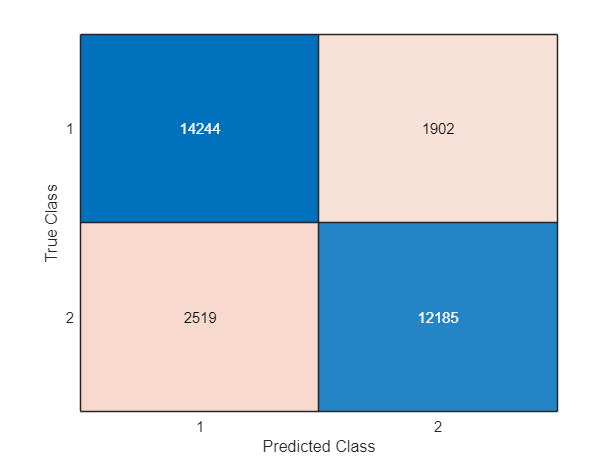


% Confusion matrix
predicted = predict(eeg_classifier.Trained{1}, balanced_eeg_data(:,1:4));
eeg_confusion_matrix = confusionmat(balanced_eeg_data(:,end), predicted);
figure
confusionchart(eeg_confusion_matrix)


% Statistical tests
%------------------------------------------------------------------------------------------------
% Permutation test
true_labels = balanced_eeg_data(:,end);
predicted_labels = predicted;

actual_accuracy = sum(true_labels == predicted_labels,'all')/numel(predicted_labels);

num_permutations = length(true_labels)*100;
permuted_accuracy = zeros(1,num_permutations);
for k = 1:num_permutations
    shuffled_labels = predicted_labels(randperm(length(predicted_labels)));

    permuted_accuracy(k) = sum(true_labels == shuffled_labels,'all')/numel(shuffled_labels);
end

actual_accuracy

actual_accuracy = 0.8567

permuted_accuracy

permuted_accuracy =     0.5058    0.4983    0.4982    0.5049    0.4990    0.4999    0.4997    0.5032    0.5021    0.5058    0.4996    0.5073    0.5021    0.5023    0.4992    0.5058    0.5016    0.5025    0.4998    0.5014    0.4988    0.5088    0.5023    0.5057    0.4992    0.5025    0.5010    0.5061    0.5046    0.4982    0.5025    0.5025    0.5033    0.5021    0.5021    0.5055    0.4996    0.5021    0.5009    0.5070    0.5022    0.4997    0.5027    0.5021    0.4997    0.5080    0.5038    0.4996    0.5054    0.5032


p_value = (sum(permuted_accuracy >= actual_accuracy) + 1) / (num_permutations + 1)

p_value = 9.9990e-05


if p_value < 0.05
    disp('Classifier performance is statistically significant. Null hypothesis is rejected, the classifier performance is better than random chance.');
else
    disp('Classifier performance is not statistically significant. Null hypothesis is not rejected.');
end

Classifier performance is statistically significant. Null hypothesis is rejected, the classifier performance is better than random chance.


%------------------------------------------------------------------------------------------------
fprintf("=======================================================================================")

EMG

% Fix class imbalance with Synthetic Minority Over-sampling Technique (SMOTE)
%balanced_emg_data = mySMOTE(emg_features, 5, sort(emg_features(:,end))); % unbalanced data, k neighbors, labels ordered/sorted
balanced_emg_data = emg_features;

% Train classifier using 5 fold cross validation
emg_classifier = fitcdiscr(balanced_emg_data(:,1:5), balanced_emg_data(:,end),"DiscrimType","linear","CrossVal","on","KFold",5,"SaveMemory","on"); % LDA
save("trained_classifiers\emg_classifier.mat","emg_classifier");

fprintf("=======================================================================================")

% Accuracy
accuracy_first_fold = loss(emg_classifier.Trained{1}, balanced_emg_data(:,1:5), balanced_emg_data(:,end));
disp(['LDA 1st fold accuracy : ', num2str((1-accuracy_first_fold)*100), '%']);

LDA 1st fold accuracy : 45.5494%


accuracy_second_fold = loss(emg_classifier.Trained{2}, balanced_emg_data(:,1:5), balanced_emg_data(:,end));
disp(['LDA 2nd fold accuracy : ', num2str((1-accuracy_second_fold)*100), '%']);

LDA 2nd fold accuracy : 45.4266%


accuracy_third_fold = loss(emg_classifier.Trained{3}, balanced_emg_data(:,1:5), balanced_emg_data(:,end));
disp(['LDA 3rd fold accuracy : ', num2str((1-accuracy_third_fold)*100), '%']);

LDA 3rd fold accuracy : 45.6722%


accuracy_fourth_fold = loss(emg_classifier.Trained{4}, balanced_emg_data(:,1:5), balanced_emg_data(:,end));
disp(['LDA 4th fold accuracy : ', num2str((1-accuracy_fourth_fold)*100), '%']);

LDA 4th fold accuracy : 45.7336%


accuracy_fifth_fold = loss(emg_classifier.Trained{5}, balanced_emg_data(:,1:5), balanced_emg_data(:,end));
disp(['LDA 5th fold accuracy : ', num2str((1-accuracy_fifth_fold)*100), '%']);

LDA 5th fold accuracy : 46.4702%



formatSpec = '%.2f';
disp(['LDA average accuracy : ', num2str((1-mean([accuracy_first_fold, accuracy_second_fold, accuracy_third_fold, accuracy_fourth_fold, accuracy_fifth_fold]))*100, formatSpec), '% (+-', num2str(std([accuracy_first_fold, accuracy_second_fold, accuracy_third_fold, accuracy_fourth_fold, accuracy_fifth_fold])*100, formatSpec), '%)']);

LDA average accuracy : 45.77% (+-0.41%)


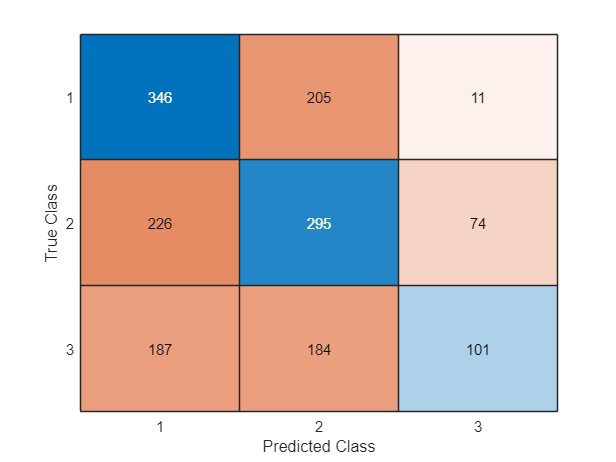


% Confusion matrix
predicted = predict(emg_classifier.Trained{1}, balanced_emg_data(:,1:5));
emg_confusion_matrix = confusionmat(balanced_emg_data(:,end), predicted);
figure
confusionchart(emg_confusion_matrix)


% Statistical tests
%------------------------------------------------------------------------------------------------
% Permutation test
true_labels = balanced_emg_data(:,end);
predicted_labels = predicted;

actual_accuracy = sum(true_labels == predicted_labels,'all')/numel(predicted_labels);

num_permutations = length(true_labels)*100;
permuted_accuracy = zeros(1,num_permutations);
for k = 1:num_permutations
    shuffled_labels = predicted_labels(randperm(length(predicted_labels)));

    permuted_accuracy(k) = sum(true_labels == shuffled_labels,'all')/numel(shuffled_labels);
end

actual_accuracy

actual_accuracy = 0.4555

permuted_accuracy

permuted_accuracy =     0.3432    0.3450    0.3401    0.3432    0.3481    0.3438    0.3493    0.3309    0.3346    0.3653    0.3370    0.3450    0.3407    0.3659    0.3376    0.3364    0.3432    0.3432    0.3401    0.3634    0.3346    0.3364    0.3579    0.3432    0.3524    0.3419    0.3235    0.3450    0.3640    0.3272    0.3554    0.3413    0.3432    0.3591    0.3364    0.3475    0.3468    0.3622    0.3260    0.3548    0.3444    0.3517    0.3573    0.3517    0.3524    0.3524    0.3303    0.3499    0.3567    0.3327


p_value = (sum(permuted_accuracy >= actual_accuracy) + 1) / (num_permutations + 1)

p_value = 9.9990e-05


if p_value < 0.05
    disp('Classifier performance is statistically significant. Null hypothesis is rejected, the classifier performance is better than random chance.');
else
    disp('Classifier performance is not statistically significant. Null hypothesis is not rejected.');
end

Classifier performance is statistically significant. Null hypothesis is rejected, the classifier performance is better than random chance.


%------------------------------------------------------------------------------------------------
fprintf("=======================================================================================")

[https://www.jmlr.org/papers/volume11/ojala10a/ojala10a.pdf](https://www.jmlr.org/papers/volume11/ojala10a/ojala10a.pdf) 

[https://www.sciencedirect.com/science/article/pii/S2213158214000485](https://www.sciencedirect.com/science/article/pii/S2213158214000485) 

Response time

N/A

Turtlebot3 and gazebo

N/A